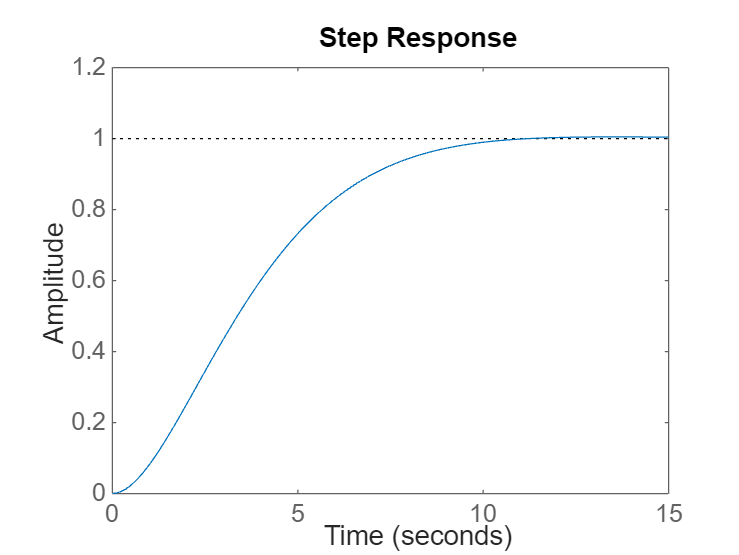

ans = struct with fields:
         RiseTime: 5.9033
    TransientTime: 9.3754
     SettlingTime: 9.3754
      SettlingMin: 0.9061
      SettlingMax: 1.0044
        Overshoot: 0.4445
       Undershoot: 0
             Peak: 1.0044
         PeakTime: 13.5853


% Definir el tiempo de asentamiento deseado
    Ts = 10; % segundos

    % Calcular los parámetros de la función de transferencia
    zeta = 0.865; % coeficiente de amortiguamiento (ajustar según sea necesario)
    wn = 4 / (zeta * Ts); % frecuencia natural

    % Crear la función de transferencia
    sys = tf(wn^2, [1, 2*zeta*wn, wn^2]);
    step(sys); stepinfo(sys)

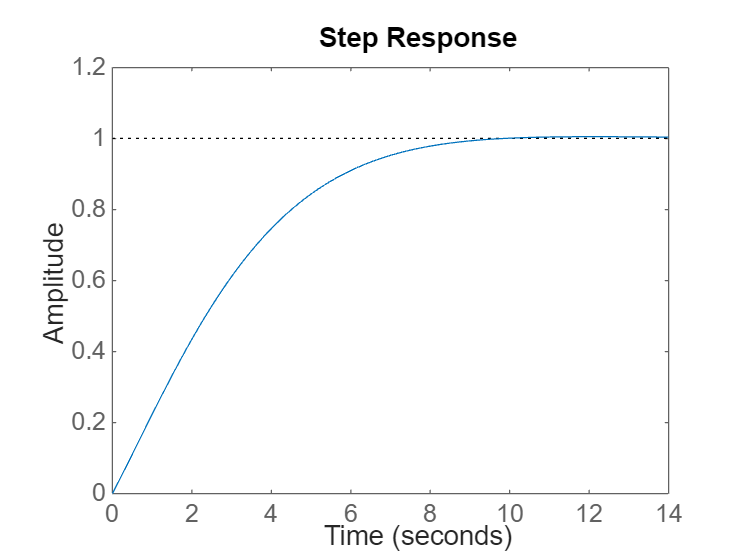

ans = struct with fields:
         RiseTime: 5.3699
    TransientTime: 8.0796
     SettlingTime: 8.0796
      SettlingMin: 0.9027
      SettlingMax: 1.0051
        Overshoot: 0.5067
       Undershoot: 0
             Peak: 1.0051
         PeakTime: 12.0886


ref.km  = 0.21261;
ref.bm  = 1;
ref.am1 = 0.8;
ref.am2 = 0.2126;
sys2=tf([ref.km ref.km*ref.bm],[1 ref.am1 ref.am2]);
step(sys2); stepinfo(sys2)